Index exceeds matrix dimensions.

Error in prtDataSetClass/plot (line 1385)
                zlabel(fNames{3})

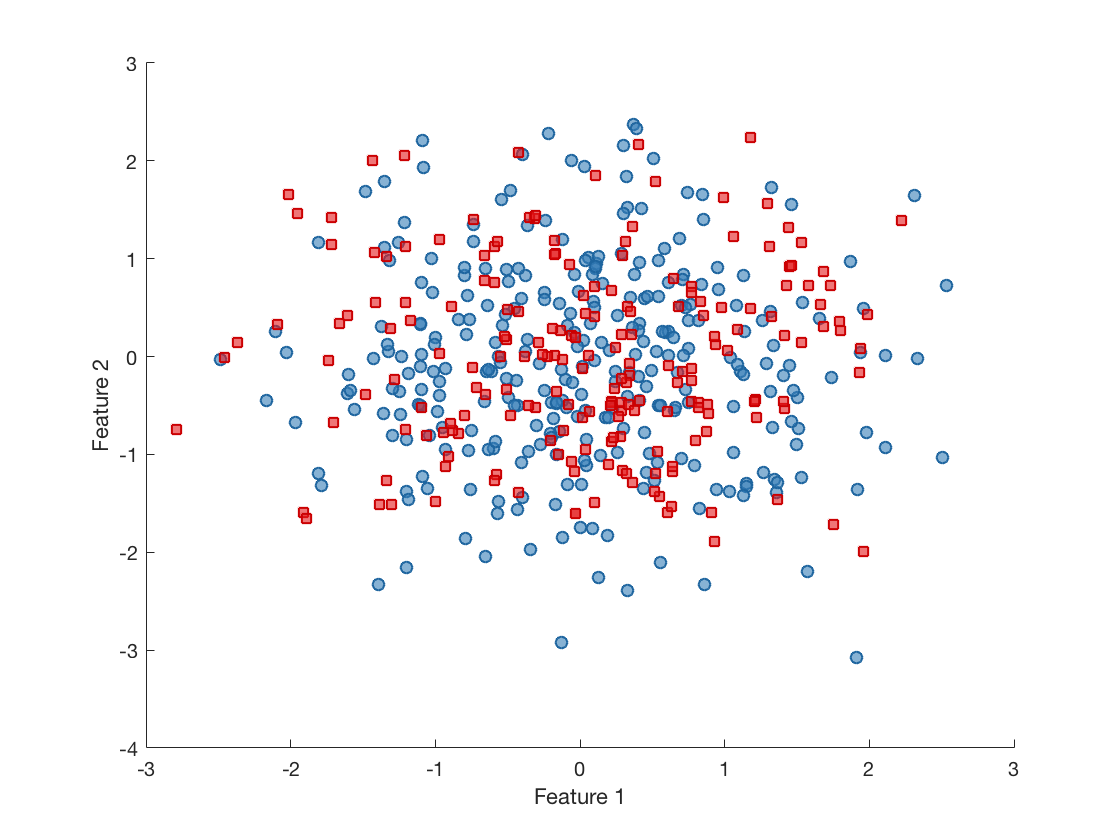

D = 4;
n1 = 200;
n0 = 300;
X1 = randn(n1,D);
X0 = randn(n0,D);
X = cat(1,X1,X0);
Y1 = ones(n1,1);
Y0 = zeros(n0,1);
Y = cat(1,Y1,Y0);
ds_train = prtDataSetClass(X,Y);
plot(ds_train)

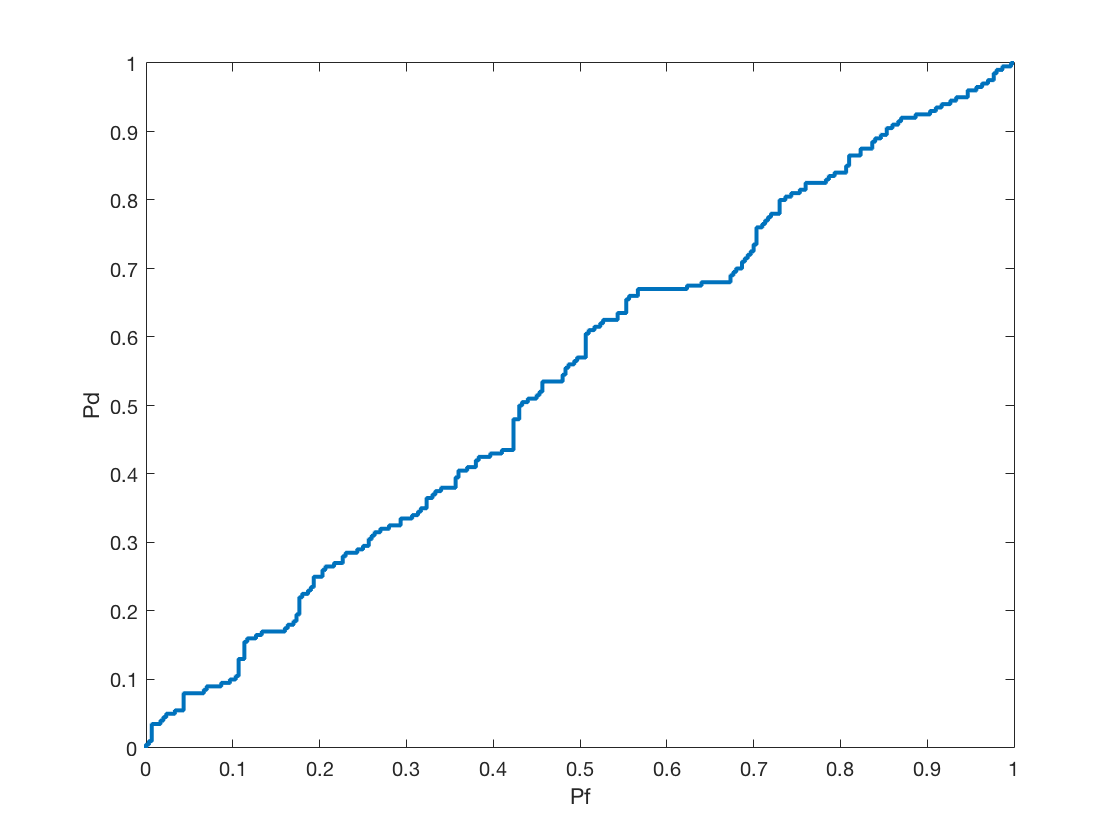

cls = prtClassFld;
cls_trained = cls.train(ds_train);
results = cls_trained.run(ds_train);
prtScoreRoc(results)

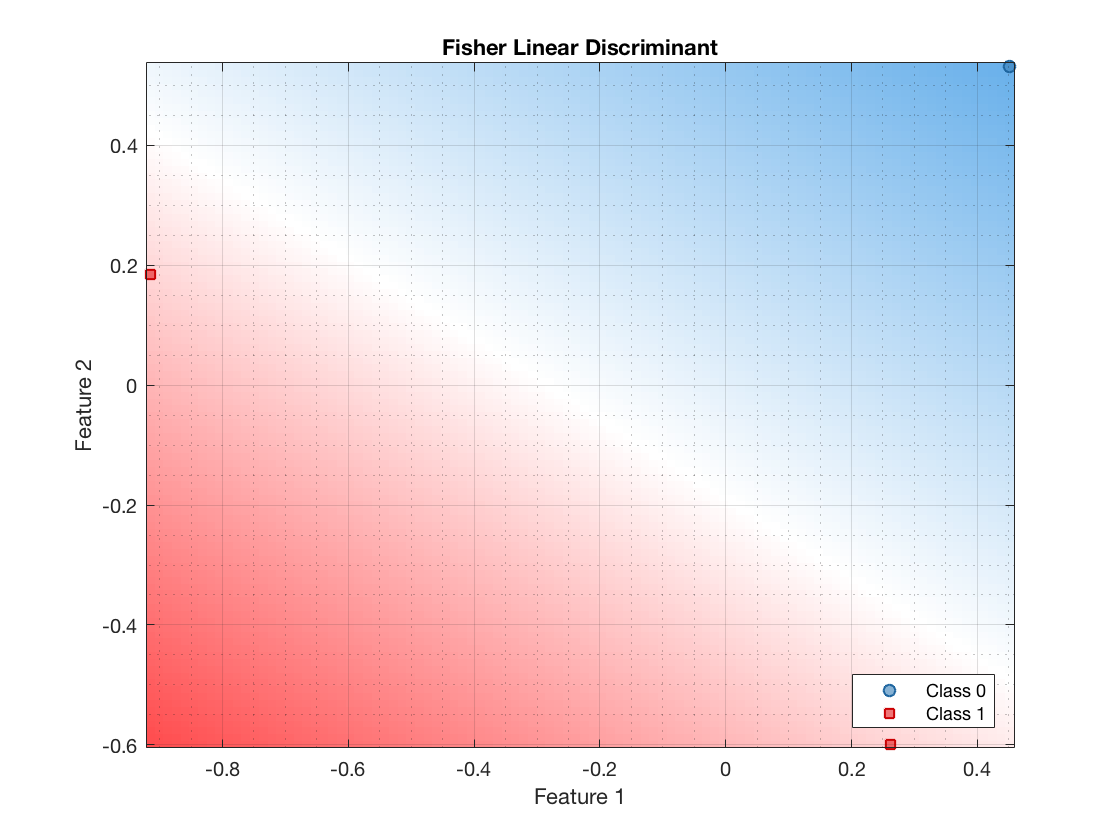

plot(cls_trained)